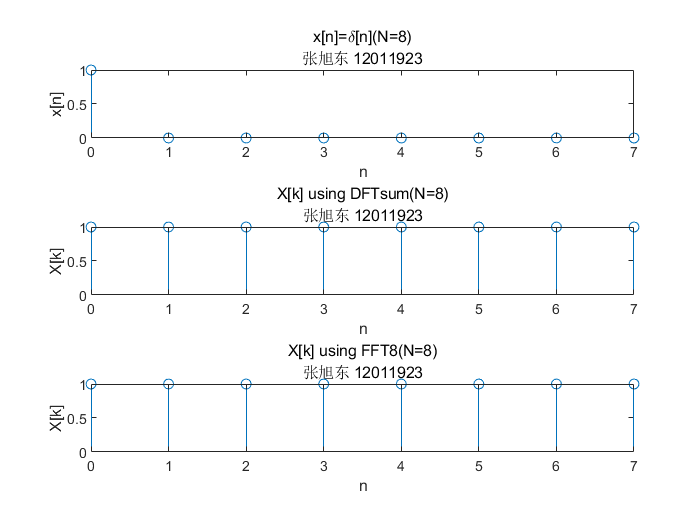

%5.3.2
N=8;
n=0:1:N-1;

x1=[1 zeros(1,N-1)];
X1=FFT8(x1);
X=DFTsum(x1);
figure;
subplot(3,1,1);
stem(n,x1);
xlabel('n');
ylabel('x[n]');
title(['x[n]=\delta[n](N=8)' newline '张旭东 12011923']);
subplot(3,1,2);
stem(n,X);
xlabel('n');
ylabel('X[k]');
title(['X[k] using DFTsum(N=8)' newline '张旭东 12011923']);
subplot(3,1,3);
stem(n,X1);
xlabel('n');
ylabel('X[k]');
title(['X[k] using FFT8(N=8)' newline '张旭东 12011923']);

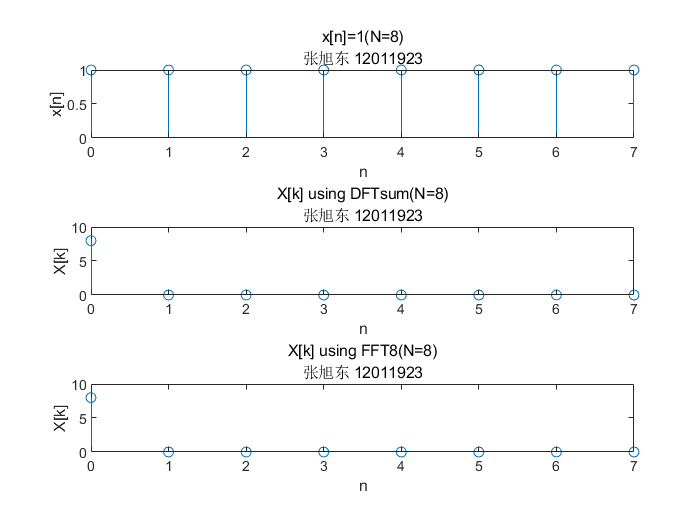


x2=ones(1,N);
X2=DFTsum(x2);
X22=FFT8(x2);
figure;
subplot(3,1,1);
stem(n,x2);
xlabel('n');
ylabel('x[n]');
title(['x[n]=1(N=8)' newline '张旭东 12011923']);
subplot(3,1,2);
stem(n,abs(X2));
xlabel('n');
ylabel('X[k]');
title(['X[k] using DFTsum(N=8)' newline '张旭东 12011923']);
subplot(3,1,3);
stem(n,abs(X22));
xlabel('n');
ylabel('X[k]');
title(['X[k] using FFT8(N=8)' newline '张旭东 12011923']);


x3=exp(1j*2*pi*n/N);
X3=DFTsum(x3);
X33=FFT8(x3);
figure;
subplot(3,1,1);
stem(n,x3);

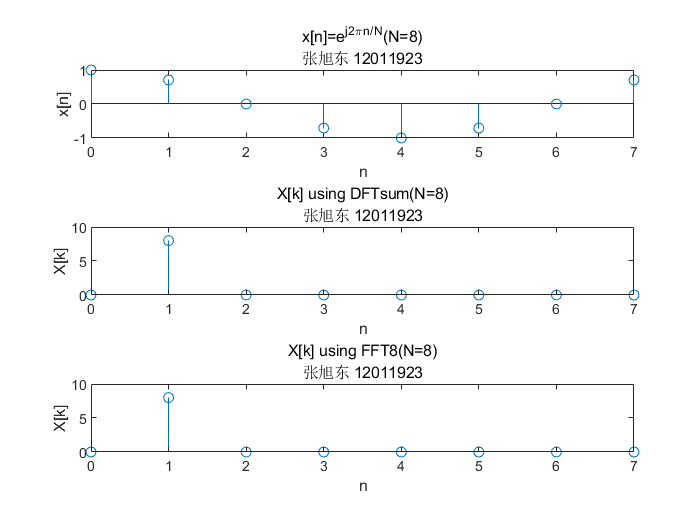

xlabel('n');
ylabel('x[n]');
title(['x[n]=e^j^2^\pi^n^/^N(N=8)' newline '张旭东 12011923']);
subplot(3,1,2);
stem(n,abs(X3));
xlabel('n');
ylabel('X[k]');
title(['X[k] using DFTsum(N=8)' newline '张旭东 12011923']);
subplot(3,1,3);
stem(n,abs(X33));
xlabel('n');
ylabel('X[k]');
title(['X[k] using FFT8(N=8)' newline '张旭东 12011923']);